%% To start fresh
clear; clc;
close all;

% 1D example: 
%% Test funciton
tstf = 20;
d= 3; % dimension

%% Number of iterations and grid points
%number of initial points
n_init = 70; % for 1D pick small number say 3. for 2D pick at least 20
% number of iterations
n_iter = 50;

acquisition = 'PI'; % PI EI LB
acquisition_scale = 100; % for LB use 1 for EI and PI you might need to use -100 or -1000
beta =0.1; % Start with 3 for LB and 0 for EI and PI

rng(2)


[value,x_min,domain] = optim_test_fncs(ones(1,d), tstf);
fnc = @(x) optim_test_fncs(x, tstf);
% Remark: the BayesOpt expects bounded domains. If domain is not bounded,
% artificially set domain to a bounded region that we want to explore.
%domain = [-10 ; 10];


% number of grid points in each dimension
n_grid= 50; % number of grid points in each dimension, used both for plotting (in 1 and
% 2 dimensions), and for Kriging reconstructions

%% Evaluation noise
sig2= 1e-2; % pick small if evals are not noisy

%% Acquisition function
% Options: 'LB' lower bound, 'EI' expected improvement, 'PI' probability of improvement parameter: choose beta= 0 for EI and PI
% beta changes how the acquisition function balances mean and variance. for
% PI and EI, small beta can help locate the minimum with higher accuracy but
% it can also get stuck in a local minimum. Bigger beta results in more
% explorative behaviour ( going after areas of high uncertainty)



%%Covariance function
% Options: 'Matern', 'Gaussian'
% for matern you can use 0.5,1.5,2.5, for Gaussian nu is unused
cov_fun = 'Matern';
nu = 1.5; % for matern you can use 0.5,1.5,2.5, for Gaussian nu is unused

%% fixed parameters
% fixed param  =[ rho sigma^2 nu sigma_ep^2 rho_cov] (rho_cov is rho for
% Gaussian and kappa for Matern) 
% for isotropic case set rho = ones(1,d) and rho_cov = 0,
% for anisotropic set rho = zeros(1,d) and rho_cov = 1
fixed_param = [zeros(1,d) 0 nu sig2 1]; % parameters set to 0 will be estimated

Plotting = 1; % only select for test functions in 1D and 2D
log_color = 0; % use log scale for the color bar

% some of the acquisition funcitons (EI,PI) are between 0 and 1. To show them on the same plot as the objective funciton you may need to scale them.
% also multiply by -1 for EI and PI (to undo (-1) we mutliplied by to get a
% minimization problem.


[xy, par_est]= BayesOpt(fnc,cov_fun,acquisition,domain,fixed_param,beta,n_init,n_iter,n_grid, Plotting,log_color,acquisition_scale);


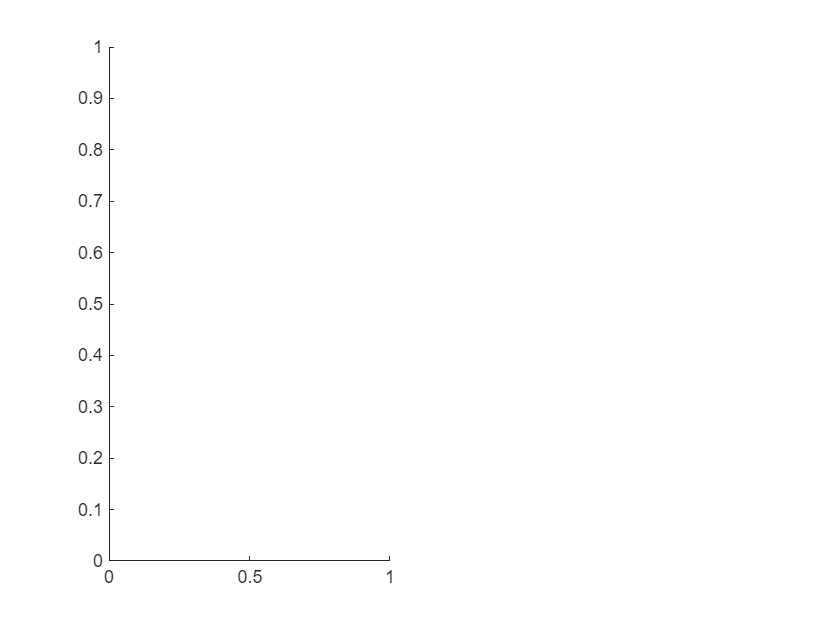

% compute improvement path
[X,F] = improvement_path(xy,2);
figure
subplot(121)

plot(vecnorm(X-x_min,2,2), 'LineWidth', 1)

Arrays have incompatible sizes for this operation.

Related documentation

hold on
xline(n_init,'Color', [0, 0, 0], 'LineWidth', 0.6)
axis tight
ylim padded
xlim padded

legend('','Optimization Start')
title('||x_{min}-x||')

subplot(122)
plot(F, 'LineWidth', 1)% might need to use logscale 

xline(n_init,'Color', [0, 0, 0], 'LineWidth', 0.6)
legend('','Optimization Start')
title('f_{min}')


**Visualizing the acuisition funciton **

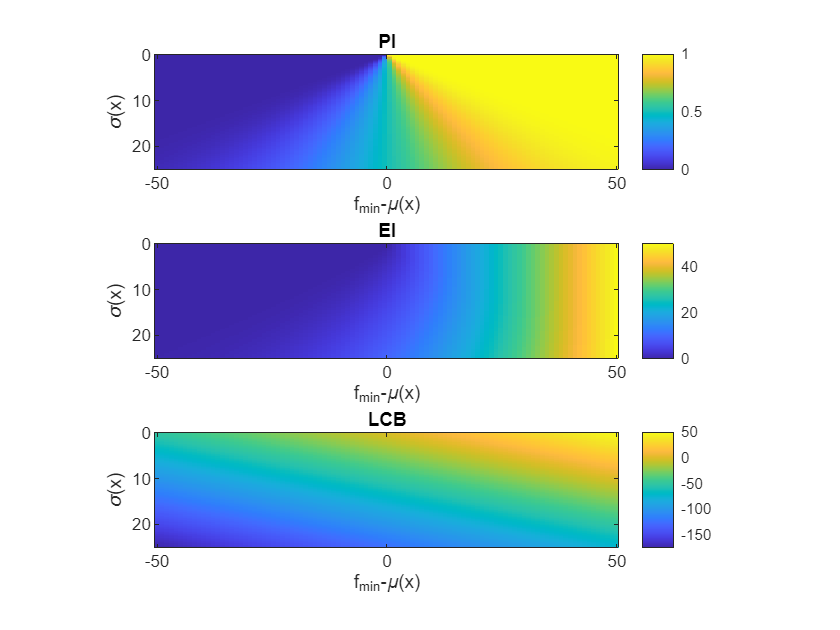

Del = linspace(-50,50,100);
SD = linspace(0,25,100);
[X, Y] = meshgrid(Del, SD);
% PI
pi = normcdf((X)./Y);


impr = (X);
ze1= impr./Y;

% EI
ei = (impr.*normcdf(ze1)+ Y .* normpdf(ze1));


% LCB
l = (X-5.*Y);


figure
subplot(311)
imagesc(Del, SD, pi); 
colorbar;                 % Add a color bar for reference
axis equal tight;         % Adjust axis scaling
title('PI');
xlabel('f_{min}-\mu(x)');
ylabel('\sigma(x)');
subplot(312)
imagesc(Del, SD, ei);         % Display data as an image
colorbar;                 % Add a color bar for reference
axis equal tight;         % Adjust axis scaling
title('EI');
xlabel('f_{min}-\mu(x)');
ylabel('\sigma(x)');
subplot(313)
imagesc(Del, SD, l);         % Display data as an image
colorbar;                 % Add a color bar for reference
axis equal tight;         % Adjust axis scaling
title('LCB');
xlabel('f_{min}-\mu(x)');
ylabel('\sigma(x)');

function [X_min,F_min] = improvement_path(evals,d)
n = length(evals(:,end));

X_min = zeros(n,d);
F_min = zeros(n,1);

for i = 1:n
    [m,I] = min(evals(1:i,d+1));

    X_min(i,:) = (evals(I,1:d));
    F_min(i) = m;
end
end